## TIRF pipleine walkthrough

- Import ND2 file.

- Background subtract.

- Mask each video.

- Find mask overlaps among channels.

- Get intensity traces based on overlap.

- Analyze traces.

### 1. Import files:

First, get a list of the paths for the ND2 files that we want to process:

%import a sample datafile
pathlist = getFileList(); % gets a list of datafiles that you specify in a filebrowser
disp(pathlist);

    '/home/colin/data/imaging/TIRF_slides/20200305_guanine/Cy5DNA…'    '/home/colin/data/imaging/TIRF_slides/20200305_guanine/Cy5DNA…'    '/home/colin/data/imaging/TIRF_slides/20200305_guanine/Cy5DNA…'    '/home/colin/data/imaging/TIRF_slides/20200305_guanine/Cy5DNA…'



### 2. Background subtract:

Next, import the videos into RAM and subtract background.

The first input to the function is the list of paths, generated above, and the second parameter is the size of the gaussian sigma to use in x,y,z space for the background subtraction. In this case, backgrounding is done with Eric Wait's HIP.HighPassFilter algorithm.

processed_videos = processND2(pathlist,[10 10 0]); % imports list of ND2 files with the bioformats reader, returns a 5D array: [x, y, z, c, t]

Reading series #1
    ........................................................................
    ........................................................................
    ........................................................................
    ........................................................................
    ........................................................................
    ........................................................................
    ........................................................................
    ........................................................................
    ..............
Done with /home/colin/data/imaging/TIRF_slides/20200305_guanine/Cy5DNA_A565_4xCblsyn_neg_2xwash_001.nd2
Reading series #1
    ........................................................................
    ........................................................................
    ...................................................................

This process will print a bunch of things for each video and probably take a good amount of time. Make sure you have enough RAM to store all of the videos you are loading!

Notice the format that is used when videos are imported. I'm putting them into a cell array that keeps all the relevant data organized. Cell arrays are handy because they can store any kind of data in each cell. Column 1 is the path to each of the ND2 files, and column 2 is the 5D array containing the background-subtracted video.

processed_videos

processed_videos = 4×2 cell array
    {'/home/colin/data/imaging/TIRF_slides/20200305_guanine/Cy5DNA_A565_4xCblsyn_neg_2xwash_001.nd2'}    {5-D single}
    {'/home/colin/data/imaging/TIRF_slides/20200305_guanine/Cy5DNA_A565_4xCblsyn_neg_2xwash_002.nd2'}    {5-D single}
    {'/home/colin/data/imaging/TIRF_slides/20200305_guanine/Cy5DNA_A565_6xG_pos_2xwash_001.nd2'     }    {5-D single}
    {'/home/colin/data/imaging/TIRF_slides/20200305_guanine/Cy5DNA_A565_6xG_pos_2xwash_002.nd2'     }    {5-D single}


For the subsequent processing, I will be passing this variable back into each function and storing the result in the same variable (see the LoGMask call below). This saves some RAM and keeps things organized.

### 3. Mask each video:

Next we need to isolate the particles in the video. To do this we use a LoG (Laplacian of Gaussian) filter to find the edges of each particle. A threshold then enables us to generate a mask, which we can then filter for particles that persist in the video and are of the right size.

`LoGMask` is one of the most complex functions in the pipeline. For any analysis, it is also likely that you'll be running this function a bunch of times while changing parameters until you like the result. There are quite a few parameters to change, but the main one is probably `LoG_thresholds`, which allows you to specify the mask threshold for each channel.

Below I have added sliders to be able to play around with each of the parameters.

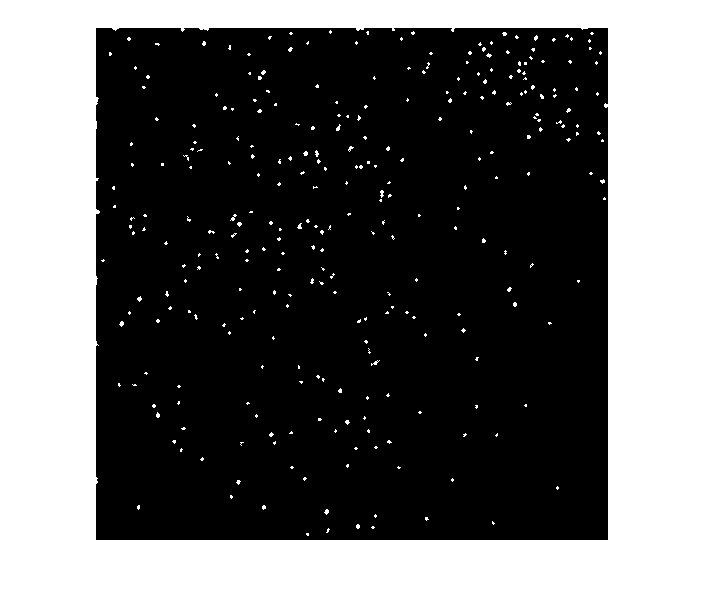

sigma = 1;
ch1_logthresh = -650;
ch2_logthresh = -50;
size_range_lower = 7;
size_range_upper = 30;
signal_count_limit = 5;
dispchannel = 2;

test = LoGMask(processed_videos(3,:), [sigma sigma 0], [ch1_logthresh ch2_logthresh], [], signal_count_limit, [size_range_lower size_range_upper], [], false);
imshow(test{1,3}(:,:,1,dispchannel),[]); % Show the mask for the first channel after LoGing and thresholding.

Above is an example of what a mask looks like. This is a single frame that represents the locations of interest on the slide across all the timepoints in the video (it is a projection across time).

Now we can run these parameters on the rest of the data.

processed_videos = LoGMask(processed_videos, [sigma sigma 0], [ch1_logthresh ch2_logthresh], [], signal_count_limit, [size_range_lower size_range_upper], [], false);

### 4. Find overlapping spots:

Now that we have a mask of each channel, let's see if any of the spots across the two channels overlap.

`batchFindOverlap` is used in a similar fashion to `LoGMask`. The processed videos cell array is passed in and the same variable is used to store the result. The second and third parameters specify the channels that you want to compare for overlap. The fourth parameter allows you to specify if the results should be opened in imageJ. The final parameter specified the overlap percent required for spots to be counted as overlapping.

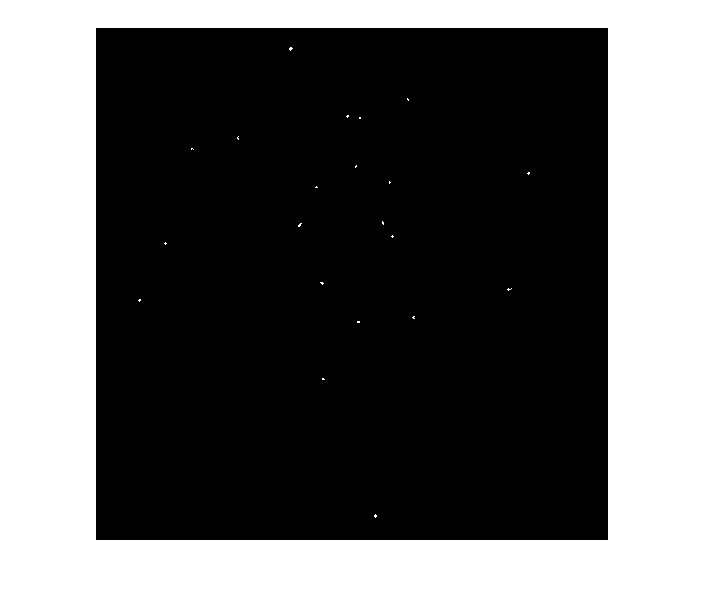

processed_videos = batchFindOverlap(processed_videos,1,2,false,.5);
imshow(processed_videos{3,4},[]);

In the above image you can see the spots that fit the overlapping criteria. It's typical in the data that we gathered so far to only have 5 to 10 spots overlapping out of hundreds.

processed_videos

processed_videos = 4×5 cell array
    {'/home/colin/data/imaging/TIRF_slides/20200305_guanine/Cy5DNA_A565_4xCblsyn_neg_2xwash_001.nd2'}    {5-D single}    {512×512×1×2 single}    {512×512 logical}    {1×3 double}
    {'/home/colin/data/imaging/TIRF_slides/20200305_guanine/Cy5DNA_A565_4xCblsyn_neg_2xwash_002.nd2'}    {5-D single}    {512×512×1×2 single}    {512×512 logical}    {1×3 double}
    {'/home/colin/data/imaging/TIRF_slides/20200305_guanine/Cy5DNA_A565_6xG_pos_2xwash_001.nd2'     }    {5-D single}    {512×512×1×2 single}    {512×512 logical}    {1×3 double}
    {'/home/colin/data/imaging/TIRF_slides/20200305_guanine/Cy5DNA_A565_6xG_pos_2xwash_002.nd2'     }    {5-D single}    {512×512×1×2 single}    {512×512 logical}    {1×3 double}


Let's take a look at the structure of `processed_videos` again. Now, in addition to the path in column 1 and the backgrounded video in column 2 we have the masks in column 3, the overlap images in column 4, and the spot counts in column 5. The spot counts show the number of spots in each channel as well as the number of overlapping spots (respectively).

### 5. Get intensity traces based on overlap:

Now we are ready to use the overlapping spots to track the intensities across the single-particle video. `batchGetTraces` uses the mask on the background subtracted video, and finds the intensity for each spot across time for both channels. Since this is the end of the video analysis, the result of this method is not placed into the cell array. All videos that are passed into the method are analyzed and the resulting trace data is combined. Thus, if you are analyzing your control alongside your experimental data (which you should be) you will need to call the function twice. For example, if the first video in the cell array was my negative control and the second video was my experimental:

negative_control = processed_videos(1:2,:); % Note here that paraentheses are used for the indexing instead of curly braces so that the variable stays as a cell array.
experimental = processed_videos(3:4,:);

traces_negative = batchGetTraces(negative_control,5);
traces_experimental = batchGetTraces(experimental,5);
clear negative_control experimental;

size(traces_experimental)

ans =     34     2   295


Notice here the shape/size of the array that is returned by `batchGetTraces`. There are 6 spots, each with two channels. The third column represents the time dimension. Because MatLab only uses rectangular matricies, the size of this dimension is the lenght of the longest video.

Now let's plot these traces as a heatmap. `pHeatmap` is a utility function to do so. Notice how I have specified that I want to see the first channel in the function call below.

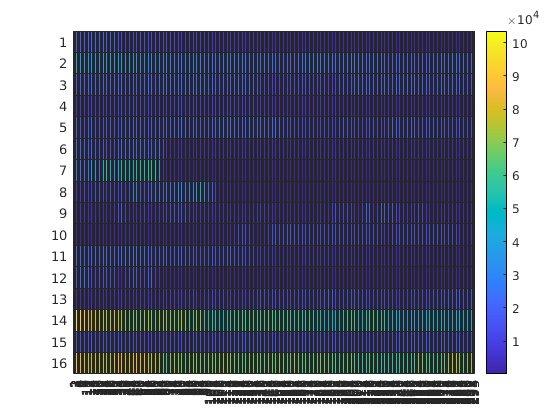

pHeatmap(traces_negative(:,1,:));

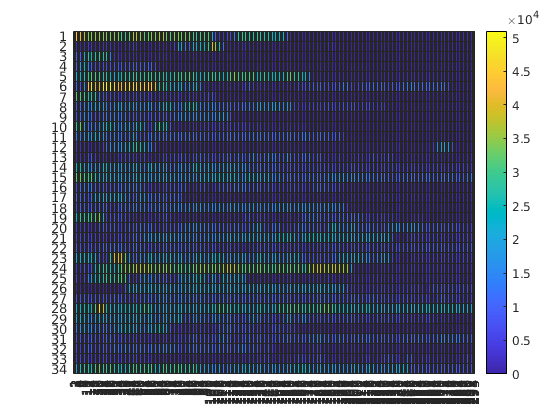

pHeatmap(traces_experimental(:,1,:));